# QIBC analysis

YFP: chromatin-bound MCM nuclear intensity

FarRed: EdU incorporation

## Load data

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\A42_Data\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%rows = [4 5];
conditions = {
    '24 hr MCM preext DMSO',[2:3],2,1:37; 
    '18 hr MCM preext DMSO',[2:3],3,1:37; 
    '15 hr MCM preext DMSO',[2:3],4,1:37;  
    '12 hr MCM preext DMSO',[2:3],5,1:37; 
    '0 hr MCM preext DMSO',[2:3],6,1:37; 
    
    '24 hr MCM preext DAB',[2:3],7,1:37; 
    '18 hr MCM preext DAB',[2:3],8,1:37; 
    '15 hr MCM preext DAB',[2:3],9,1:37;  
    '12 hr MCM preext DAB',[2:3],10,1:37; 
    '0 hr MCM preext DAB',[2:3],11,1:37; 
    
    '24 hr MCM total DMSO',[4],2,1:37; 
    '18 hr MCM total DMSO',[4],3,1:37; 
    '15 hr MCM total DMSO',[4],4,1:37;  
    '12 hr MCM total DMSO',[4],5,1:37; 
    '0 hr MCM total DMSO',[4],6,1:37; 
    
    '24 hr MCM total DAB',[4],7,1:37; 
    '18 hr MCM total DAB',[4],8,1:37; 
    '15 hr MCM total DAB',[4],9,1:37;  
    '12 hr MCM total DAB',[4],10,1:37; 
    '0 hr MCM total DAB',[4],11,1:37; 
    
    '24 hr pRB DMSO',[5],2,1:37; 
    '18 hr pRB DMSO',[5],3,1:37; 
    '15 hr pRB DMSO',[5],4,1:37;  
    '12 hr pRB DMSO',[5],5,1:37; 
    '0 hr pRB DMSO',[5],6,1:37; 
    
    '24 hr pRB DAB',[5],7,1:37; 
    '18 hr pRB DAB',[5],8,1:37; 
    '15 hr pRB DAB',[5],9,1:37;  
    '12 hr pRB DAB',[5],10,1:37; 
    '0 hr pRB DAB',[5],11,1:37; 
    
    '24 hr cdc6 DMSO',[7],2,1:37; 
    '18 hr cdc6 DMSO',[7],3,1:37; 
    '15 hr cdc6 DMSO',[7],4,1:37;  
    '12 hr cdc6 DMSO',[7],5,1:37; 
    '0 hr cdc6 DMSO',[7],6,1:37; 
    
    '24 hr cdc6 DAB',[7],7,1:37; 
    '18 hr cdc6 DAB',[7],8,1:37; 
    '15 hr cdc6 DAB',[7],9,1:37;  
    '12 hr cdc6 DAB',[7],10,1:37; 
    '0 hr cdc6 DAB',[7],11,1:37; 
    
};

S = loadData_A42(conditions, dataDir);

**Set Thresholds**

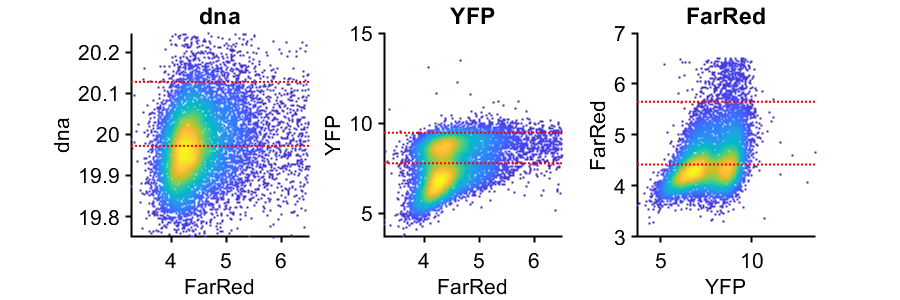

%% Set gates G1
cond=4;
gateval = struct();
gates = {'dna','YFP','FarRed'};
plotting = {'FarRed','FarRed','YFP'};
prctiles = {[50 95], [50 95],[50 95],[50 95],[50 95]};

figure('pos',[0 0 length(gates)*300 300 ])

for i = 1:length(gates)
    inds = S(cond).dna > 2^19.75 & S(cond).dna < 2^20.25 & S(cond).FarRed < 2^6.5;
    
    ydata = S(cond).(gates{i})(inds,:);
    xdata = S(cond).(plotting{i})(inds,:);
    
    gateval.([gates{i} '_G1']) = prctile(ydata, prctiles{i});
    
    subplot(1,length(gates),i)
    dscatter(real(log2(xdata)),real(log2(ydata)));
    hline( log2(gateval.([gates{i} '_G1'])))
    ylabel(gates{i});
    xlabel(plotting{i});
    title(gates{i});
    
end


EdUThresh = 6;
G1dna = [2^19.75 2^20.25];

Plot histograms of MCM all cells 

gatedata = {};

%12 hr pRB DMSO, DAB G1
conds = [5 3 8];
conds = [5 4 9];
yval = 'YFP';

gateVals = {'dna','FarRed','YFP'};
rangeVals = {G1dna, [-Inf gateval.FarRed_G1(2)],[-Inf 2^11]}; 

for i = 1:length(conds)
    condition = conds(i);
    ydata = log2(S(condition).(yval)); %.*S(condition).area);

    totalGate = true(size(ydata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end    
    ydata = ydata(totalGate);
    if length(ydata) > 2000
        ydata = randsample(ydata,2000,false);
    end
    gatedata = [gatedata {ydata}];
    length(ydata)
end

ans = 2000

ans = 2000

ans = 2000



%12 hr pRB DMSO, DAB early S
conds = [3 8];
conds = [4 9];
yval = 'YFP';

gateVals = {'dna','FarRed','YFP'};
rangeVals = {G1dna, [ gateval.FarRed_G1(2) Inf],[-Inf 2^11]}; 

for i = 1:length(conds)
    condition = conds(i);
    ydata = log2(S(condition).(yval)); %.*S(condition).area);

    totalGate = true(size(ydata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end    
    ydata = ydata(totalGate);
        if length(ydata) > 2000
        ydata = randsample(ydata,2000,false);
    end
    gatedata = [gatedata {ydata}];
        length(ydata)

end

ans = 2000

ans = 2000

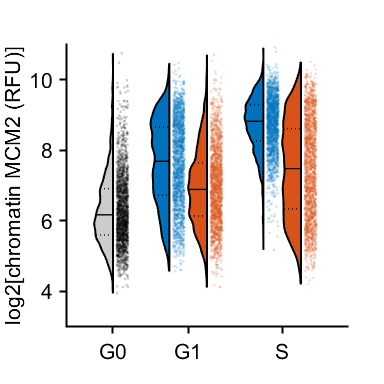

ally = cell2mat(gatedata');
groups = vertcat(1*ones(size(gatedata{1})), 2*ones(size(gatedata{2})), 3*ones(size(gatedata{3})),4*ones(size(gatedata{4})), 5*ones(size(gatedata{5})));
group_list = 1:max(groups)+1;
offsetx = floor((group_list - 1)/2) * .5;
xkey = group_list(1:end-1) + offsetx(2:end);

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','distWidth',.8,'widthDiv',[2 1],'xValues',xkey);
set(h{1},'EdgeColor',[0 0 0 ],'LineWidth',1.5)
% cols = [14 113 186; 193 39 45]/255;
cols = lines(2);
groupcol = [ 0 0 0; cols([1 2],:); cols([1 2],:)];
set(h{1},{'FaceColor'},{[.8 .8 .8],cols(1,:),cols(2,:),cols(1,:),cols(2,:)}')
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(xkey(groups)'+jit, (ally), 4,groupcol(groups,:),'filled','MarkerFaceAlpha',.2);
ylabel('log2[chromatin MCM2 (RFU)]')
xticks([1 xkey(2:2:length(xkey)-1)+.5])
xticklabels({'G0','G1','S'})
ylim([3 11])
% xtickangle(45)
pbaspect([1 1 1])
print_pdf([pwd() '\Figs\mcm2_compare'])

Plot histograms of MCM early S phase cells

gatedata = {};


%15 hr pRB DMSO, DAB early S
conds = [3 8];
% conds = [4 9];
yval = 'FarRed';

gateVals = {'dna'};
rangeVals = {G1dna, [gateval.FarRed_G1(2) Inf]}; 

for i = 1:length(conds)
    condition = conds(i);
    ydata = log2(S(condition).(yval)); %.*S(condition).area);

    totalGate = true(size(ydata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end    
    ydata = ydata(totalGate);
    gatedata = [gatedata {ydata}];
    sum(ydata > 5.75)/length(ydata)
end

ans = 0.5011

ans = 0.3553



figure('Units', 'Inches', 'Position', [0, 0, 4, 4]);
 nhist(gatedata,'npoints','pdf','binfactor',1,'samebins','fsize',16,'legend',conditions(conds,1),'minbins',50)

ans = 1×2 cell array
    {'15 hr MCM preext DMSO: number of points=12380, mean=6.90, std=2.41, '}    {'15 hr MCM preext DAB: number of points=13543, mean=5.56, std=1.55, '}


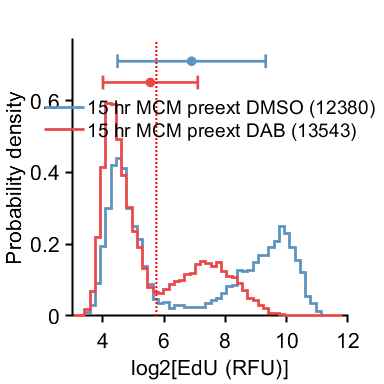

xlabel('log2[EdU (RFU)]')
ylabel('Probability density')
xlim([3 12])
axis square
vline(5.75)
print_pdf([pwd() '\Figs\eduhist_noG0.pdf'])